**LAB: Rozwiązywanie liniowych obwodów elektrycznych **

**Cel:**

Celem ćwiczenia jest obliczanie równań liniowych w postaci macierzowej na przykładzie przepływów prądu w obwodzie liniowym składającym się z rezystorów i źródeł napięcia stałego. 

Schemat przykładowego obwodu przedstawiono na Rysunku 1. 

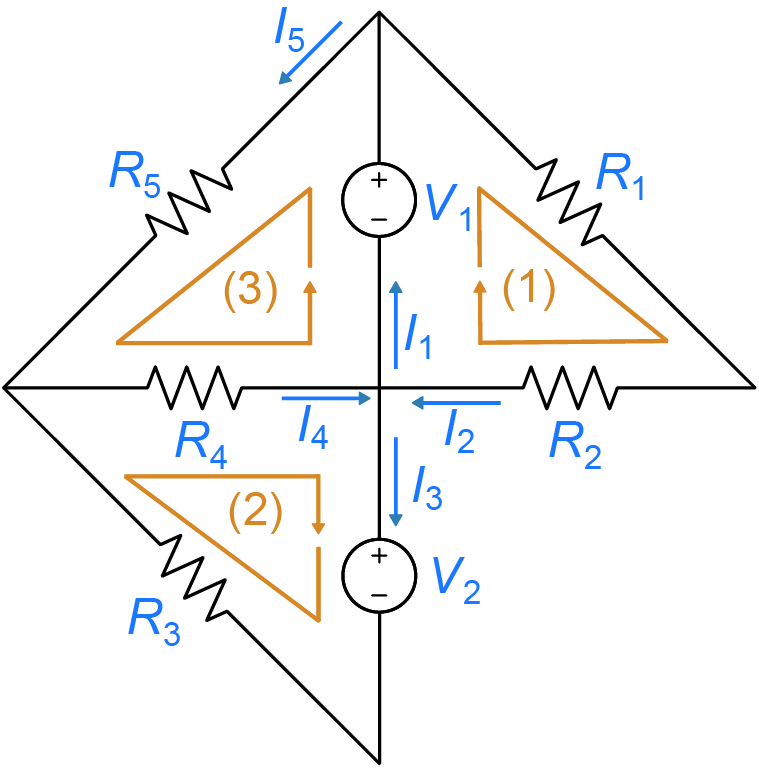

Rysunek 1. Przykładowy schemat obwodu elektrycznego

Na Rysunku 1 są trzy zamknięte pętle obwodu oznaczone (1), (2) i (3).

Poszczególne prądy w obwodzie są oznaczone I1, I2, I3, I4.

Zastosowanie prawa Kirchhoffa prądu do węzła centralnego daje:


$$I_2 + I_4 = I_1 + I_3$$


Zastosowanie drugiego prawa Kirchhoffa (napięciowego) do trzech pętli powoduje dodanie trzech dodatkowych równań:


$$\begin{array}{rl} 
\ V_1 - I_2 R_1 - I_2 R_2  &= 0
\\
- V_2 - I_3 R_3 - I_4 R_4  &= 0
\\
\ V_1 - I_5 R_5 - I_4 R_4  &= 0
\end{array}$$


Jest pięć nieznanych prądów, ale tylko cztery równania. Aby dokończyć reprezentację, wymagane jest kolejne zastosowanie prawa prądów Kirchhoffa. Dla górnego węzła:


$$I_1 = I_2 + I_5$$


Należy pamiętać, że istnieją dodatkowe pętle i węzły, do których można zastosować prawo Kirchhoffa – jednak wszystkie one spowodują wystąpienie powtarzających się warunków.

Na podstawie Prawa Kirchhoffa definiujemy układ równań liniowych, gdzie każdy węzeł i gałąź są reprezentowane przez równanie, a rezystancje i napięcia stanowią współczynniki w macierzy. 

**Wyprowadzenie postaci macierzowej równań**

Aby zapisać te równania w postaci macierzowej $\mathbf{AI} = \mathbf{b}$, należy zdefiniować  wektor rozwiązania:

   
$$\mathbf{I} = \left( \matrix{ I_1 \cr I_2 \cr I_3 \cr I_4 \cr I_5 } \right)$$


Przeniesienie wszystkich zmiennych wyrazów na lewą stronę, a stałych wyrazów na prawą stronę otrzymujemy:

  $\begin{array}{rl} 
\ I_2 R_1 + I_2 R_2  &= V_1
\\
I_3 R_3 + I_4 R_4  &=  -V_2
\\
I_5 R_5  + I_4 R_4  &= V_1  
\\
I_1 - I_2 + I_3 - I_4 &= 0
\\
I_1 - I_2 - I_5 &= 0
\end{array}$        (1)

Powyższy układ równań (1) nalezy przekształcic do postaci macierzowej $\mathbf{AI} = \mathbf{b}$:

A = $\left(\begin{array}{ccccc}
0 & R_1 +R_2  & 0 & 0 & 0\\
0 & 0 & R_3  & R_4  & 0\\
0 & 0 & 0 & R_4  & R_5 \\
1 & -1 & 1 & -1 & 0\\
1 & -1 & 0 & 0 & -1
\end{array}\right)$

b=$\left(\begin{array}{c}
V_1 \\
-V_2 \\
V_1 \\
0\\
0
\end{array}\right)$

Należy obliczyć iloczyn macierzy, aby sprawdzić, czy forma macierzy jest zgodna z oryginalnym systemem (1).

Poniższy skrypt przekształca układ równań do postaci macierzowej i oblicza prądy w każdej gałęzi obwodu, wykorzystując funkcje MATLAB do rozwiązywania układów równań.

% Parametry obwodu (rezystancja w omach, napięcie w woltach)
R1 = 10; R2 = 200; R3 = 10000; R4 = 2000; R5 = 330;
V1 = 1.5; V2 = 12;

% Macierz współczynników i wektor stałych
A = [
        0,  R1+R2, 0,   0,  0;
        0,  0,     R3,  R4, 0;
        0,  0,     0,   R4, R5;
        1,  -1,    1,   -1, 0;
        1,  -1,    0,   0,  -1;
    ];

b = [
     V1;
    -V2;
     V1;
     0;
     0
    ];

% Rozwiązanie równania prądów w każdej gałęzi
I = A\b;

% Wyświetlanie wyników
disp('Natężenie prodów w gałęziach obwodu wynosi:');

Natężenie prodów w gałęziach obwodu wynosi:


disp(I);

    0.0089
    0.0071
   -0.0013
    0.0005
    0.0018



W sprawozdaniu należy dobrać dowolny, indywidulany obwód elektryczny i przeprowadzić analize wartości prądów w każdej gałezi. 